# Point Target

## Constants

c = physconst("lightspeed");
fc = 9.5e9;

## Swerling model

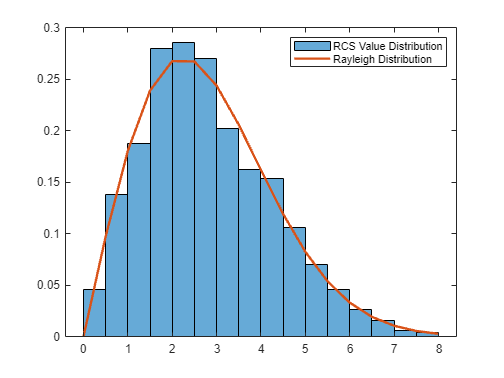

% create RCS signature with fluctuation model 
sigFluc = rcsSignature("FluctuationModel","Swerling1");

nTrial = 1000;
rcsValues = zeros(nTrial,1);
for ii = 1:nTrial
    rcsValues(ii) = db2mag(sigFluc.value(0,0,fc));
end

h = histogram(rcsValues,"Normalization","pdf");

% plot Rayleigh distribution
hold on
b = raylfit(rcsValues);
pd = makedist("Rayleigh","b",b);
x = h.BinEdges;
y = pd.pdf(x);
plot(x,y,"LineWidth",2)
legend(["RCS Value Distribution","Rayleigh Distribution"])
hold off

## RCS model from shape

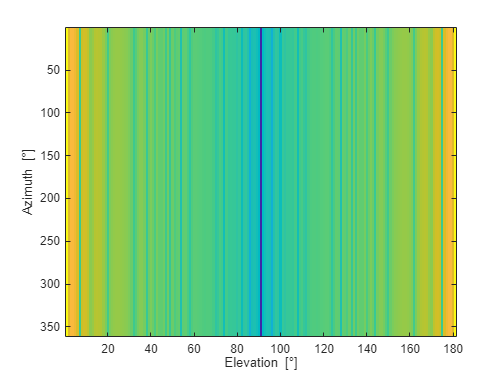

az = -180:180;
el = -90:90;
% Create RCS signature with disc shape
sigShape = rcsSignature("Pattern",pow2db(rcsdisc(1,c,fc,az,el)+eps), ...
    "Frequency",[0 20e9],"Azimuth",az,"Elevation",el);
rcsMap = zeros(length(az),length(el));
for e = 1:length(el)
    rcsMap(:,e) = sigShape.value(az,el(e),fc);
end
figure
imagesc(rcsMap)
axis tight
ylabel("Azimuth [\circ]")
xlabel("Elevation [\circ]")

clearvars -except sigFluc 